# **Vision Artificial. GIEC y GITT.**

# **	Sistemas de Vision Artificial. GIC, GII y GISI.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Tema 5: Transfer Learning

# **Parte I. **GoogLeNet

## GoogLeNet

El primer paso va a ser estudiar las características de GoogLeNet.

GoogLeNet es un modelo preentrenado que ha sido entrenado en un subconjunto de la base de datos ImageNet. El modelo se ha entrenado con más de un millón de imágenes, tiene 144 capas y puede clasificar imágenes en 1.000 categorías de objetos (por ejemplo, teclado, ratón, lápiz y muchos animales).

Esta función requiere el paquete de soporte **Deep Learning Toolbox™ Model *****for GoogLeNet Network*****.** Si no ha instalado el paquete de soporte, la función proporciona un enlace de descarga.

clear all

[net,classNames] = imagePretrainedNetwork("googlenet"); % para versiones R2024a o superiores 
% net = googlenet; % para versiones R2023b o inferiores 

La variable `net` representa una red convolucional profunda. Puede inspeccionar las capas de la red haciendo referencia a la propiedad `Layers` de la variable, utilizando la indexación `variable``.``Property`:

ly = net.Layers;

Se va a examinar la primera capa (entrada) de la red. Una propiedad importante para una capa de entrada es `InputSize`, que es el tamaño (dimensiones) de las imágenes que la red espera como entrada. 

inlayer = ly(1);
insz = inlayer.InputSize

## predicción de GoogLeNet

Se va a cargar la imagen `"football.jpg"` para obtener la predicción de GoogLeNet.

**Se pide:**

- Cambie el **tamaño** de la imagen, con la función [imresize](https://es.mathworks.com/help/matlab/ref/imresize.html?s_tid=srchtitle_support_results_1_imresize), para adaptarlo al tamaño de las imagenes de entrada de GoogLeNet.

img = imread("football.jpg");
imshow(img)
title(sprintf('image size:%dx%dx%d',size(img,1),size(img,2),size(img,3)))

img = imresize( ); % RELLENAR Aquí!  
imshow(img)
title(sprintf('image size:%dx%dx%d',size(img,1),size(img,2),size(img,3)))


**Se pide:**

- Para realizar una predicción con una sola imagen, utilice la función [`predict`](https://es.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html). Esta función solo admite los siguientes formatos: `dlarray, full double/single/logical array, `o un compatible` gpuArray`. La imagen tiene el tipo de datos `uint8`, luego para realizar la predicción con la red neuronal de conviertir la imagen al tipo de datos [`single`](https://es.mathworks.com/help/matlab/ref/single.html).

Nota. SI dispone de GPU (puede verificarlo con [`canUseGPU`](https://es.mathworks.com/help/matlab/ref/canusegpu.html?s_tid=srchtitle_support_results_1_canUseGPU)) y quiere utilizarla debera convertir los datos a [`gpuArray`](https://es.mathworks.com/help/parallel-computing/gpuarray.html?s_tid=srchtitle_support_results_1_gpuArray). 

-  La función predict devuelve las puntuaciones para todas clases. Guardelas en la variable `scores`. Finalmente, convierta las predicciones a etiquetas con la función [scores2label](https://es.mathworks.com/help/deeplearning/ref/scores2label.html?s_tid=srchtitle_support_results_1_scores2label).

img_predict = [];% RELLENAR Aquí!  

scores = predict( );% RELLENAR Aquí!  
[label,score] = scores2label( );% RELLENAR Aquí!  

Se puede crear un gráfico de barras de las puntuaciones de predicción. Hay que tener en cuenta que es difícil leer el gráfico dado que incluye 1000  puntuaciones de predicción.

bar(scores);

Para hacer las lejible el gráfico sólo se mostrarán los resultados con `scores` mayores que `0.005`. 

**Se pide:**

- Rellene el siguiente script para mostrar sólo las clases que cumplan con el score > 0.005.

highscores  =  []; % RELLENAR Aquí!  
bar( ); % RELLENAR Aquí!  
xticklabels(classNames(highscores))

# **Parte II.** Transfer Learning

La transferencia del aprendizaje es un proceso que consiste en elegir una red de deep learning preentrenada y ajustarla para aprender una tarea nueva. Utilizar la transferencia del aprendizaje es normalmente un proceso más rápido y sencillo que entrenar una red desde cero. Puede transferir de forma rápida las características aprendidas a una nueva tarea con menos cantidad de datos.

## Flujo de trabajo típico de transferencia del aprendizaje 

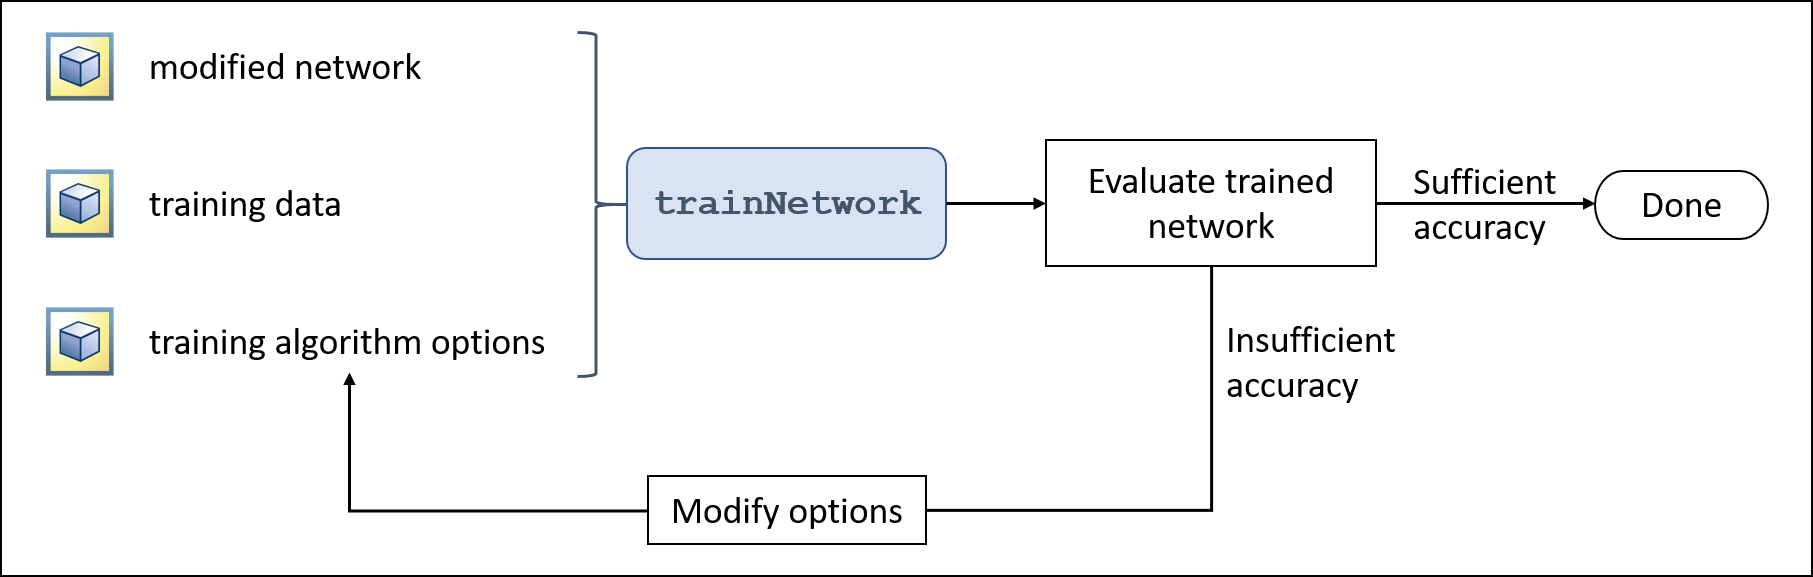

Para realizar la transferencia del aprendizaje necesita crear tres componentes:

- Un arreglo de capas que representan la arquitectura de red.  Para la transferencia del aprendizaje, este arreglo de capas se crea  modificando una red preexistente, como **GoogLeNet**.  

- Imágenes con **etiquetas** conocidas, para utilizarlas como datos de entrenamiento. Por lo general se proporcionan como **almacén de datos**.

- Una variable que contenga las **opciones** que controlan el comportamiento del algoritmo de entrenamiento.

Estos tres componentes se proporcionan como entradas a la función, `trainNetwork` que devuelve la red entrenada como salida. 

Se recomienda probar el rendimiento de la red entrenada que acaba de crear. Si no es el adecuado, intente ajustar alguna de las opciones de  entrenamiento y volver a realizar el entrenamiento.  

clear all
close all
clc

## **1) Extraer datos**

En este ejemplo se va a utiliza un conjunto de datos de varios miles de fotos de flores. El conjunto de datos de flores (Flowers`/)` contiene cinco subdirectorios, uno por clase:

- `  daisy/ (margarita)`

- `  dandelion/ (diente de león)`

- `  roses/ (rosas)`

- `  sunflowers/ (girasoles)`

- `  tulips/ (tulipanes)`

 **Nota:** todas las imágenes tienen licencia CC-BY, los creadores se enumeran en el archivo LICENSE.txt.

Cree un almacén de datos de imágenes. Un almacén de datos de imágenes permite almacenar grandes colecciones de datos de imágenes, incluidos los que no caben en la memoria, y leer eficazmente lotes de imágenes durante el entrenamiento de una red neuronal. Especifique la carpeta con las imágenes extraídas e indique que los nombres de las subcarpetas corresponden a las etiquetas de las imágenes.

% Datos de entramiento, validación y Test
pathToImages = "Flowers";
flowers_ds = imageDatastore(pathToImages,"IncludeSubfolders",true,"LabelSource","foldernames");
flowerNames = flowers_ds.Labels;

## 2) Dividir datos para Entrenamiento, Validación y Prueba

Puede utilizar la función [`splitEachLabel`](https://es.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) para dividir las imágenes de un almacén de datos en varios almacenes de datos independientes.

`[``ds1``,..,dsN]` `=` `splitEachLabel``(``imds``, ``p1,...,pN ``)`

Las proporciones `p1,...,pN ` (valores de 0 a 1) indican la proporción de imágenes con cada etiqueta de `imds` que debería estar contenida en `ds1,...,` `dsN`.

**Rellene** el siguiente script para dividir los datos en un **70%** de las imágenes para el **entrenamiento**, el 15% para validación y el 15% restante para prueba. Incluya al final `"randomized" `para que se elijan de forma aleatoria.

[flowers_Train, flowers_Val, flowers_Test] = splitEachLabel(); % Rellene Aquí! 

## 3) Seleccionar una red preentrenada y prepararla para el entrenamiento

Para abrir Deep Network Designer, en la pestaña **Apps**, en **Machine Learning and Deep Learning**, haga clic en el icono de la app. Como alternativa, puede abrir la app desde la línea de comandos:

deepNetworkDesigner

Deep Network Designer proporciona una selección de redes de clasificación de imágenes que han aprendido representaciones ricas en características adecuadas para una amplia gama de imágenes. La transferencia del aprendizaje funciona mejor si las imágenes son similares a las imágenes utilizadas originalmente para entrenar la red.

Seleccione **GoogLeNet** de la lista de redes preentrenadas y haga clic en **Open**.

Explore la gráfica de red. Para ampliarla con el ratón, utilice **Ctrl** + la rueda de desplazamiento. Para desplazarse, utilice las teclas de flecha o mantenga pulsada la rueda de desplazamiento y arrastre el ratón. Seleccione una capa para ver sus propiedades. Quite la selección de todas las capas para ver el resumen de la red en el panel **Properties**.

Seleccione la capa de entrada de imagen, `'input'`. Puede ver que el tamaño de entrada para esta red es de 224 por 224 por 3 píxeles.

Guarde el tamaño de entrada en la variable `inputSize`.

inputSize = [224 224 3];

Para usar una red preentrenada para la transferencia del aprendizaje, debe modificar el número de clases de forma que coincida con el nuevo conjunto de datos. 

***NOTA****: Antes de la versión R2023b: Para adaptar la red a los nuevos datos, debe remplazar las capas en vez de desbloquearlas. En las nuevas versiones puede hacer clic en ****Unlock Layer**** y modificar los parámetros.*

En primer lugar,  reemplace la capa totalmente conectada (fullyConnectedLayer). Las capas totalmente conectadas necesitan un número determinado de neuronas. Debería haber  una neurona para cada clase de salida. Para añadir una capa totalmente conectada, localice la sección **Convolution and Fully Connected (Convolución y totalmente conectada)** de la biblioteca **Layer Library**. Haga clic y arrastre una capa para añadirla al área de diseño. En el panel **Properties**, establezca **OutputSize** en `5` (para los 5 tipos de flores).

Reemplace la última capa totalmente conectada de la red por la nueva  capa recién creada. La capa que debe reemplazar se denomina `"loss3-classifier"`. Para reemplazar una capa, puede eliminar la capa existente y añadir  conexiones a la capa nueva. Para añadir conexiones, haga clic y arrastre desde la salida de una capa a la entrada de otra.

Haga clic en la última capa de la red. En el panel **Properties**, observe que **OutputSize** es 1000. La capa totalmente conectada que acaba de crear tiene un tamaño de salida **OutputSize** de 5. Esta discrepancia supondrá un problema al pasar la información  desde la nueva capa totalmente conectada a la capa de clasificación.  Para corregirlo, cree una `classificationLayer` nueva (**Output**). Reemplace la capa de clasificación existente por la capa nueva.

Ha modificado un arreglo de capas de red para la transferencia del  aprendizaje. Para utilizar la red, debe exportarla. En la barra de herramientas, haga clic en **Expor**t y guarde la red con el nombre: **net_flowers **(por defecto el nombre de la red es **net**`_1`). Una vez guardada en el espacio de trabajo la puede utilizar para el entrenamiento con los datos de especies de flores.

## 4) Aumento de datos

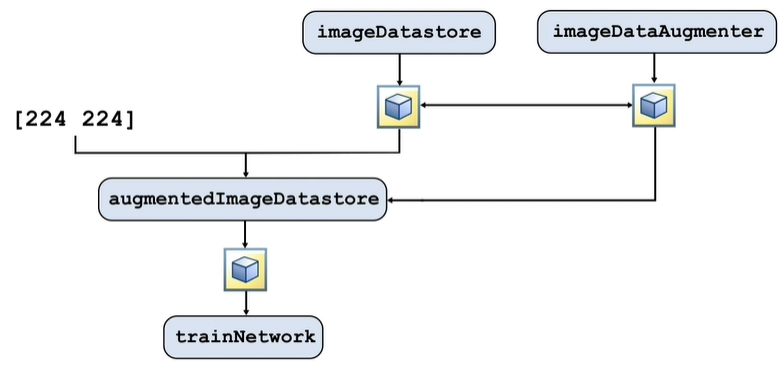

Las imágenes del almacén de datos pueden tener diferentes tamaños. Para cambiar automáticamente el tamaño de las imágenes de entrenamiento, utilice un almacén de datos de imágenes aumentado ([augmentedImageDatastore](https://es.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html?s_tid=doc_ta)). El aumento de datos también ayuda a evitar que la red se sobreajuste y memorice los detalles exactos de las imágenes de entrenamiento. Especifique en la función [imageDataAugmenter](https://es.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html?s_tid=doc_ta) las operaciones de aumento adicionales que desea realizar en las imágenes de entrenamiento. En nuestro caso: 

- voltear aleatoriamente las imágenes de entrenamiento a lo largo del eje vertical.

- Translaciones aleatorias de hasta 30 píxeles en horizontal y vertical. 

% se especifican las operaciones para el Data Aumetation
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    RandXReflection=true, ...
    RandXTranslation=pixelRange, ...
    RandYTranslation=pixelRange);

Para cambiar automáticamente el tamaño de las imágenes de validación y prueba sin realizar más aumentos de datos, utilice un almacén de datos de imágenes aumentadas sin especificar ninguna operación adicional de preprocesamiento.

% cambio del tamaño de las imágenes con Data Aumentation
aug_flowers_Train = augmentedImageDatastore(inputSize(1:2),flowers_Train, DataAugmentation=imageAugmenter); 
% cambio del tamaño de las imágenes  sin Data Aumentation
aug_flowers_Val = augmentedImageDatastore(inputSize(1:2),flowers_Val); 
aug_flowers_Test = augmentedImageDatastore(inputSize(1:2),flowers_Test);

## 5) Establecer opciones de entrenamiento

Puede ver las opciones disponibles para un algoritmo de entrenamiento específico utilizando la función `trainingOptions`.

Con esto se crea una variable `options` que contiene las opciones predeterminadas para el algoritmo de  entrenamiento “gradiente descendente estocástico con momento” (SGDM).

Especifique las siguientes opciones de entrenamiento:

- Entrenar usando el optimizador "`sgdm`" (stochastic gradient descent with momentum).

- Por lo general, el entrenamiento se realiza conservando los valores predeterminados de la mayoría de las opciones. Sin embargo, en la  transferencia del aprendizaje, se suele comenzar con un valor de `InitialLearnRate` menor que el valor predeterminado de `0.01`. En nuestro caso lo vamos a fijar a `0.001`.

- Una época (`epoch`) es un ciclo de entrenamiento completo en el conjunto total de datos de entrenamiento. Para la transferencia del aprendizaje, no es necesario entrenar durante tantas épocas. Para reducir el tiempo de entrenamiento en la CPU, el número máximo de épocas (`MaxEpochs`) se limita a **1**, ya que por defecto son 30. Después puede probar a aumentarlas. 

- Especifique los datos de validación (`ValidationData`) y la frecuencia de validación (ValidationFrequency), cada cuántas iteraciones se realiza la validación, por ejemplo **10**.

- Especifique el tamaño de minilote (`MiniBatchSize`), es decir, cuántas imágenes se pueden utilizar en cada iteración. Un minilote es un subconjunto del conjunto de entrenamiento que se usa  para evaluar el gradiente de la función de pérdida y actualizar los  pesos. Utilice **16**.

- Muestre el progreso del entrenamiento en una gráfica y monitorice la métrica de precisión (`Plots="training-progress"`).

- Deshabilite la salida detallada (`Verbose=false`).

% Ejecute y después CAMBIE los valores Aquí!  
options = trainingOptions("sgdm")

## 6) Entrenar redes neuronales

Entrene la red neuronal con la función [`trainnet`](https://www.mathworks.com/help/releases/R2024a/deeplearning/ref/trainnet.html). (para versiona anteriores a R2023b se deería utilizar [trainNetwork](https://es.mathworks.com/help/deeplearning/ref/trainnetwork.html)) Para las tareas de clasificación, utilice la pérdida de entropía cruzada. De forma predeterminada, la función `trainnet` usa una GPU en caso de que esté disponible. Para utilizar una GPU se requiere una licencia de Parallel Computing Toolbox™ y un dispositivo GPU compatible. Para obtener información sobre los dispositivos compatibles, consulte [GPU Computing Requirements](https://www.mathworks.com/help/releases/R2024a/parallel-computing/gpu-computing-requirements.html) (Parallel Computing Toolbox). De lo contrario, la función `trainnet` usa la CPU. Para especificar el entorno de ejecución, utilice la opción de entrenamiento `ExecutionEnvironment`.

Comente la opción que NO corresponda.

### Con R2024a o superior

flowers_net = trainnet(aug_flowers_Train, net_flowers, "crossentropy", options);

### `Con R2023b o inferior`

% flowers_net = trainNetwork(aug_flowers_Train,lgraph_1,options);

**Nota**: si este proceso tarda demasiado puede cargar alguna de las siguientes redes, que ya han sido entrenadas:

-  `"net_flowers1_sgdm.mat"``: `entrenada con epoch=1 usando el optimizador "`sgdm`" 

- `"net_flowers10_sgdm.mat"``: `entrenada con epoch=10 usando el optimizador "`sgdm`" 

- `"net_flowers1_adam.mat"``: `entrenada con epoch=1 usando el optimizador "adam" 

- `"net_flowers10_adam.mat"``: `entrenada con epoch=10 usando el optimizador "adam" 

# **Probar una red neuronal**

Compruebe el funcionamiento de la red entrenada con** epoch=1** y con **epoch=10** y compárelas

## `Con R2024a o superior`

Clasifique las imágenes de prueba. Para hacer predicciones con varias observaciones utilice la función [`minibatchpredict`](https://www.mathworks.com/help/releases/R2024a/deeplearning/ref/minibatchpredict.html). Para convertir las puntuaciones de predicción en etiquetas, utilice la función [`scores2label`](https://es.mathworks.com/help/deeplearning/ref/scores2label.html?searchHighlight=scores2label&s_tid=srchtitle_support_results_1_scores2label). La función `minibatchpredict` usa automáticamente una GPU en caso de que esté disponible.

classNames = categories(flowerNames);
numClasses = numel(classNames)

flwrPredsScores = minibatchpredict(); % Rellene aquí!
flwrPredsLabels = scores2label();  % Rellene aquí!

## `Con R2023b o inferior`

Clasifique las imágenes de prueba. Para hacer predicciones con varias observaciones utilice la función [classify](https://es.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html?s_tid=doc_ta). 

% flwrPreds = classify()  % Rellene aquí!

**Resultados**. Se evalúa el clasificador utilizando los resultados obtenidos para el conjunto de test, generando la matriz de confusión y calculando a partir de ésta los siguientes parámetros: `Accuracy, Macro_Recall, Macro_Precision y Macro_F1_score`.

% Rellene aquí!
